# ** OFDM Receiver Using Software Defined Radio**

This example shows how to design an orthogonal frequency division multiplexing (OFDM) receiver for a single-input single-output (SISO) channel using a software-defined radio (SDR). The OFDM receiver captures and demodulates the OFDM signal that the [OFDM Transmitter Using Software-Defined Radio](docid:usrpradio_ug#mw_5b3bfbe2-c85e-4cd6-9760-4a3700138d6b) example sends. The OFDM receiver design includes sample buffering for timing adjustment, filtering, carrier frequency adjustment, and OFDM demodulation.

## Required Hardware and Software

To run this example, you need one of these SDRs and the corresponding software support package.

- USRP™ N2xx or B2xx series radio and [Communications Toolbox Support Package for USRP Radio](https://www.mathworks.com/hardware-support/usrp.html). For information on supported radios, see [Supported Hardware and Required Software](docid:usrpradio_ug#buzc7a6-1).

- USRP E3xx, N3xx, X3xx, or X4xx series radio and [Wireless Testbench Support Package for NI USRP Radios](https://www.mathworks.com/hardware-support/ni-usrp-radios.html). For information on supported radios, see [Supported Radio Devices](docid:wt_gs#mw_74eb94c7-dcbc-40dc-8a56-cc7bc0124002).

- ADALM-PLUTO radio and the Communications Toolbox Support Package for Analog Devices® ADALM-PLUTO Radio. 

The example requires two MATLAB™ sessions, one for the transmitter and one for the receiver. You run the OFDM Transmitter Using Software-Defined Radio example in one MATLAB session to transmit the OFDM signal.

## Set OFDM Frame Parameters

Set the OFDM parameters, including the FFT length, cyclic prefix length, and number of subcarriers. The pilot subcarrier spacing and channel bandwidth are fixed at 30 KHz and 3 MHz, respectively.

After configuring the OFDM parameters, set the data parameters. Set the modulation order, code rate, number of symbols per frame, and the number of frames per transmission. 

You can enable or disable the scopes for visualization, however for long simulations, it is recommended to disable the scope. To control the display of the diagnostic output text, enable or disable the verbosity as needed. To view the decoded data in each frame, enable the print data flag

% The chosen set of OFDM parameters:
OFDMParams.FFTLength              = 128;   % FFT length
OFDMParams.CPLength               = 32;    % Cyclic prefix length
OFDMParams.NumSubcarriers         = 90;    % Number of sub-carriers in the band
OFDMParams.Subcarrierspacing      = 30e3;  % Sub-carrier spacing of 30 KHz
OFDMParams.PilotSubcarrierSpacing = 9;     % Pilot sub-carrier spacing
OFDMParams.channelBW              = 3e6;   % Bandwidth of the channel 3 MHz

% Data Parameters
dataParams.modOrder       = 4;   % Data modulation order
dataParams.coderate       = "1/2";   % Code rate
dataParams.numSymPerFrame = 30;   % Number of data symbols per frame
dataParams.numFrames      = 2000;   % Number of frames to transmit
dataParams.enableScopes   = true;                    % Switch to enable or disable the visibility of scopes
dataParams.verbosity      = false;                    % Control to print the output diagnostics at each level of receiver processing
dataParams.printData      = true;                    % Control to print the output decoded data

## Initialize Receiver Parameters

The `helperGetRadioParams` function initializes the receiver System object™  `ofdmRx`. Assign the name of the radio you are using for receiving the OFDM signal to the variable `radioDevice`. Set the receiver gain and operating center frequency.

The `helperGetRadioRxObj` function initializes the radio receiver System object.

radioDevice            = "PLUTO";   % Choose radio device for reception
centerFrequency        = 3e9;   % Center Frequency
gain                   = 10;   % Set radio gain

The `helperOFDMSetParamsSDR` function initializes transmit-specific and common transmitter and receiver parameters required for the OFDM simulation and the `helperGetRadioParams` function initializes the parameters required for the receiver System object™ radio.

[sysParam,txParam,transportBlk] = helperOFDMSetParamsSDR(OFDMParams,dataParams);
sampleRate                       = sysParam.scs*sysParam.FFTLen;                % Sample rate of signal

ofdmRx = helperGetRadioParams(sysParam,radioDevice,sampleRate,centerFrequency,gain);
[radio,spectrumAnalyze,constDiag] = helperGetRadioRxObj(ofdmRx);

 % 
 % ofdmRx                   = sdrrx('Pluto', ...
 %    'RadioID', 'usb:1', ...
 %    'CenterFrequency', centerFrequency, ...
 %    'BasebandSampleRate', sampleRate, ...
 %    "SamplesPerFrame", 32768, ...
 %    'OutputDataType', 'double', ...
 %    'GainSource', 'AGC Fast Attack');





 % 1. Define the Serial Number for the Receiver
targetSerialRx = '1044739a470b0002ffff270027b37feec0'; 

% 2. Find all connected Plutos
radios = findPlutoRadio;
rxRadioID = '';

% 3. Loop through them to find the match
for i = 1:length(radios)
    if strcmp(radios(i).SerialNum, targetSerialRx)
        rxRadioID = radios(i).RadioID; % Grab the correct 'usb:X' ID
        break;
    end
end

% 4. Error check: Did we find it?
if isempty(rxRadioID)
    error('Receiver Pluto not found! Check connection.');
end

disp(['Receiver successfully connected to: ' rxRadioID]);

Receiver successfully connected to: usb:0



% 5. Initialize the Receiver using the found ID
ofdmRx = sdrrx('Pluto', ...
    'RadioID', rxRadioID, ... 
    'CenterFrequency', centerFrequency, ...
    'BasebandSampleRate', sampleRate, ...
    'SamplesPerFrame', 32768, ...
    'OutputDataType', 'double', ...
    'GainSource', 'AGC Fast Attack');

## Execute Receiver Loop

#### Synchronization

The OFDM receiver checks the sample buffer for the synchronization symbol to find the starting point of the data frames within the received OFDM signal. The receiver correlated the received OFDM signal with the known synchronization symbol. Once the OFDM receiver detects a high correlation peak, it identifies the position where it finds the synchronization symbol as the start of the frame.  

#### Frequency Offset Estimation and Correction

The OFDM receiver estimates and corrects the frequency and timing offset introduced to the transmitted OFDM signal due to channel impairments. The OFDM receiver checks the receiver buffer for the required number of frames and performs automatic frequency correction over each symbol. The receiver averages the frequency correction across the subcarriers and then across every six symbols, considering a group of six symbols as a slot. The receiver considers the overall average value of these corrections as the frequency offset and compensates this frequency offset across the entire frame.

The receiver is considered camped to a based station upon achieving successful synchronization and channel impairment correction. 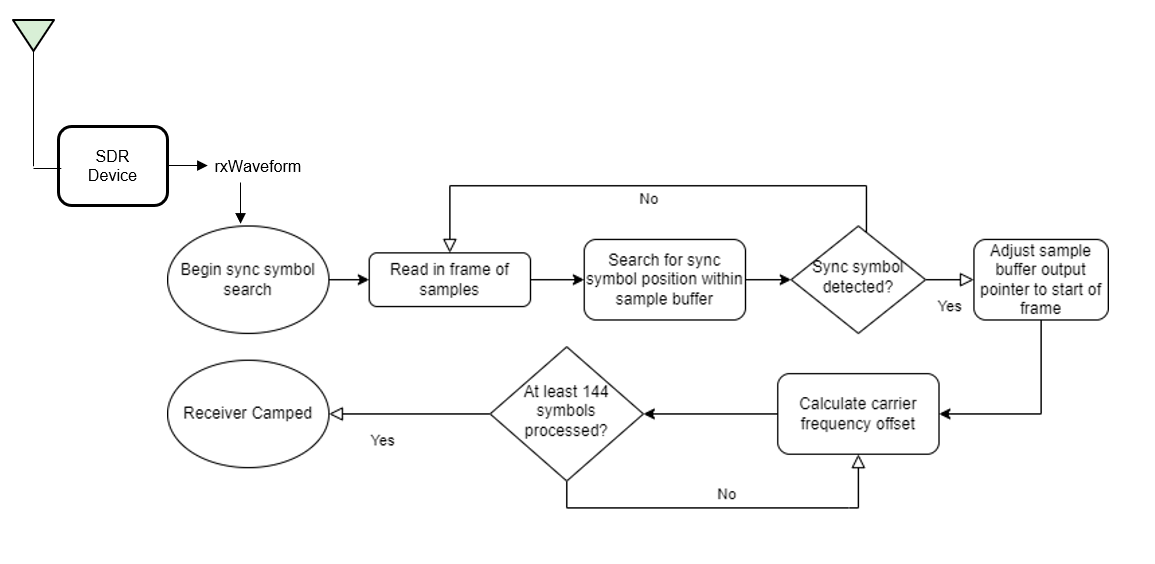

### Receiver Processing

This process is the reverse of the process that happens at the transmitter.

#### Channel Estimation and Equalization

Initially, the OFDM receiver performs channel estimation on the OFDM demodulated reference symbols. To remove the effects of time-varying fading, the receiver selects two reference symbols from adjacent frames to estimate the channel at two different points in time. The receiver then linearly interpolates the channel estimates between the two reference symbols to get the channel estimates for the header and data symbols. The `ofdmEqualize` function then equalizes the reference symbols and data symbols using the channel estimates.

#### Header Decoding

The receiver extracts and decodes the header symbols to get the data symbol parameters such as FFT length, subcarrier modulation scheme, and code rate. The receiver uses these parameters to demodulate and decode the data symbols.

#### Data Decoding

The common phase error (CPE) affects all subcarriers equally and the OFDM receiver uses the pilot symbols within the data symbols to estimate CPE. The `helperOFDMRx` function corrects the phase errors in the data symbols and the `qamdemod` function soft decodes the data subcarriers into log likelihood ratios (LLRs).

The receiver then deinterleaves the demodulated bitstream and the `vitdec` function performs maximum likelihood decoding using the Viterbi algorithm. The descrambler descrambles the decoded bits, and the `comm.CRCDetector` computes the cyclic redundancy check (CRC) and compares it with the appended CRC.

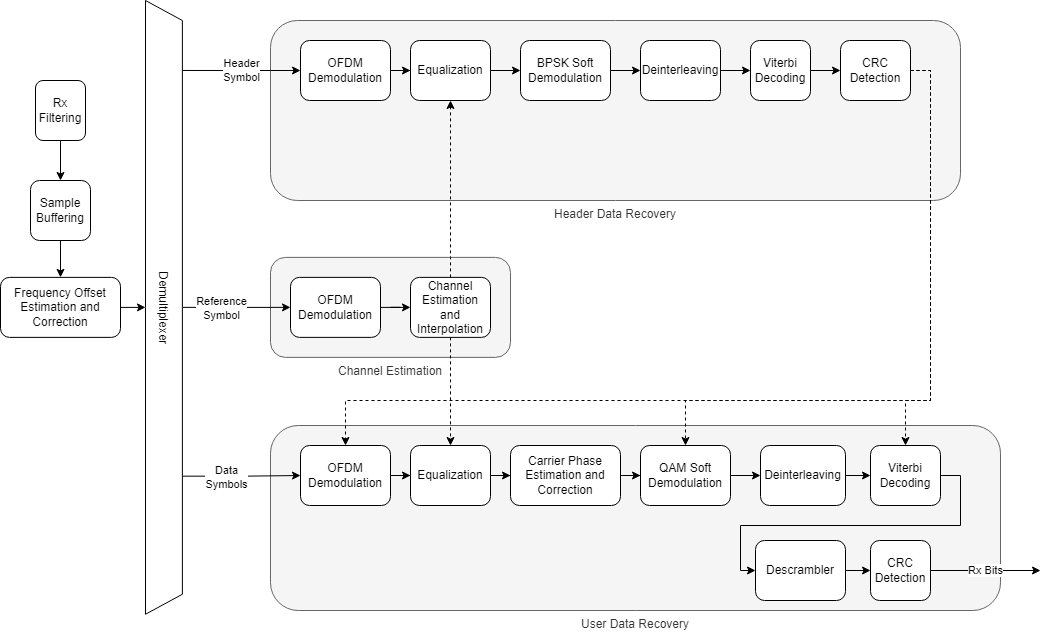

% Clear all the function data as they contain some persistent variables
clear helperOFDMRx helperOFDMRxFrontEnd helperOFDMRxSearch helperOFDMFrequencyOffset;
close all;

errorRate = comm.ErrorRate();
toverflow = 0; % Receiver overflow count
rxObj = helperOFDMRxInit(sysParam);
BER = zeros(1,dataParams.numFrames);
for frameNum = 1:dataParams.numFrames
    sysParam.frameNum = frameNum;
    [rxWaveform, ~, overflow] = radio();

    toverflow = toverflow + overflow;

    % Run the receiver front-end only when there is no overflow
    if ~overflow
        rxIn = helperOFDMRxFrontEnd(rxWaveform,sysParam,rxObj);

        % Run the receiver processing
        [rxDataBits,isConnected,toff,rxDiagnostics] = helperOFDMRx(rxIn,sysParam,rxObj);
        sysParam.timingAdvance = toff;

        % Collect bit and frame error statistics
        if isConnected
            % Continuously update the bit error rate using the |comm.ErrorRate|
            % System object
            berVals = errorRate(...
                transportBlk((1:sysParam.trBlkSize)).', ...
                rxDataBits);
            BER(frameNum) = berVals(1);
            if dataParams.printData
                % As each character in the data is encoded by 7 bits, decode the received data up to last multiples of 7
                numBitsToDecode = length(rxDataBits) - mod(length(rxDataBits),7);
                recData = char(bit2int(reshape(rxDataBits(1:numBitsToDecode),7,[]),7));
                fprintf('Received data in frame %d: %s',frameNum,recData);
            end
        end

        if isConnected && dataParams.enableScopes
            constDiag(complex(rxDiagnostics.rxConstellationHeader(:)), ...
                complex(rxDiagnostics.rxConstellationData(:)));
        end

        if dataParams.enableScopes
            spectrumAnalyze(rxWaveform);
        end
    end
end

## Establishing connection to hardware. This process can take several seconds.



Sync symbol found.
Estimating carrier frequency offset ........
Receiver camped.
.

Received data in frame 9: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wor`:V□Hm=d-□□TcC.□9□□□O	1pzM)@oi□u□cC5n,□% =)aE□□'K	-YUUS□iHwY 0□/.□wB@e#4□w{D□□□q □%v9(>\□Ej"
9	{4.□O+□l□1!wI|FR}"□/=□6□ms*□□□x□OY□>□54B.□tn'4G9>:m,4 V3□=sHv# Qa

.

Received data in frame 10:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 11: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wor`:YhHd□mC `□□F ;s_|LX~□1rpz□<FS□□u□H□'□□,	7□□□u}□hP□0gFv□Y	HwY"0□?2□p]`C04□w'
;F@,0y□;iQN□?KK!n"i□□#r□]u□□l□1)wI|J S8□?=:4□os*□□□aL'X□z□57-,□oj~Vg9>:},4 V3□9sHv"nqa

.

Received data in frame 12:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 13: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wor`:[=Helm□pc(□#0gWlZyp i_6□	;;h□U□'B"□<-e =)aE□□'K
qYUU~viHwY 0%□)D□]DP□4□w'
;Fj□0y□;iQN□>\□Aj"
;
□z□□a3□l□1!wI|Jbq(□?=*6□ms*□□□x□OXt>□54B.□tn'□G9>:m,4 V3□=sHv"nqa

.

Received data in frame 14:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 15: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wor`:V□Hm<m84□DcC	□y□□Lp~□q>□I>S□□u□H□c□□,	3□^BZI□RQ□0gF~□Y	HwY 0□□R_A2□t□□'
:>@,0y□;kVO□7N□Aj"i□□□
□pAC□l□□)wI|Jb1(□?="4□os*□□□aL'Y□z□57-,□ln~Wg7~:}(0pV3□=sHv9.r~

.

Received data in frame 16:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 17: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wor`:V□UelohP□□)□m□9□!zid`□□''w\□□□su#5tTN-=\ =)aE□
Vz□bEps'bYHwY 6□□)t8MDP0<□w'?{DCh□$:□	QN□>\□DMN□:□{4&□O/□_|nggI|[o}aO*=AvD""e□_□p□oY□>□□□P□□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 18:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 19: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wor`:YhHi@m8□□og}□!d~vr□~□1ru"□□□$4PZ+3{□□F□-3d)aYi9;ZN0p
□p
)HwY"0□m<QwQ`c34□w{D□=0y□;iQN□>N□□j"i□□□
□\A3□l□□)wI|Jb}"□/=□6□is*□□□x□oX□>□54B.□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 20:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 21: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worh3~>□□IPde<□vt4□d~@T^F[ "□
5 {3□□X`0BHB6{]0sU
>Y□□|Aw□□Y	HwY 0-□x%qc□□'S0p'
*:@,0y□;iQ}Fo^qgR#&H□H9Nx□CK>□xH□□n
 S<□?=66Ngs*□□□aL□X□>□,Sm/$8:JWO□n:}(0XH3□=sHv"nqa

.

Received data in frame 22:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 23: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Word>□QHelm8P□$xt7lZyp i$jpb□□□$4P_+□_I□D*.*W*□dL.h"□0k=6cbYHwY 01□ □□#@S&t`□'
*>@,0y□;iQN□7YG %+&"O#r□]u□□l□1)wI|J s(□?="4□es*□□□aL'Xo~□56M.□tn□□G9>:m,4 V3□=sHv"nqa

.

Received data in frame 24:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 25: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wor`:V□Ui□9□□□□kzn□9□+<Id`□9''□\}□tS□#" c6/9E =)aE□□□:□,□|□'bYHwY 0%□)t2□Ajhr(□Y□[EU□}u~QIQN□>\□DMJ□:□{4&□O/□l\zBwI|FP}#O*=MvD""m□□□x□OY□~□54R□□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 26:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 27: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wor~□?QHelhq Pf[6U□□HeLx□	!rtb□□□P4QZ+3M<D□□%□=q□+□ZhP□VgFv□Y	HwY 0□>2□rQ@c24□w'
;F@,0y□;iQN□>OK $+&"□#r□]u□□l□1,HvnJ S8□?=:4□ks*□□□aL'Y□z□57-,<oj~WgWn:}(0PV3□9sHv'.p}

.

Received data in frame 28:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 29: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worf□?QHella0□□□F□{s_|LX~□1rtb□□□$4PZ+5|? }B}□□□□us□hB□0gFv□Y	HwY 0=□!t2KDP<4□w'
;Fj□0y□;iQN□>\
Aj"i□□_z>□O+□l□1!wI|J }&□?=□6□ms*□□□x□OX\>□54Bn□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 30:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 31: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wor`>yhHellq □□□F□{s_|LX~□1rpz□<PP:□Z+3,	□□J)A□□□uS*hP□0k=&c YK*dK5vI~WJ3Ajhr8□Yz*>@,0y□;iQN□9+K!n#)"□#r□]u□□l□1)wI|J`s8□?=:4□gs*□□□aL'Y□z□56M.□ln□□G9>:m,4 V3□=sHv"nqa

.

Received data in frame 32:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 33: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wor`:HlUd-4□DcC	
y□□	p i2□□□□k8S□□u□H□□□|□M =)aE□□□:□,P|□
bYHwY 0□□r_A:□0□{g□[Dj□□ufQIQN□>\□Aj"i□□_□?□O+□l□1%wI|J }(□?=□6□,S*□□□x□OY□~□54B.□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 34:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 35: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wor`:V□Uilm□T□□orm□Y□(□□d`□/''□p=□TH|M:;6./=C =)aE□□□:□bEpr□bYK"d!0~ >W7Q@S34□w{Dj□;t*	□v□.>\□GMN□:□{4&□O/□<ljAwI|J"}!O*=MvD"!s□□□h□oXt>□54B.□tn'4G9>:m,4 V3□=sHv"nqa

.

Received data in frame 36:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 37: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wor`>[=Hell□p-C"□□vZyp i#rpzM<FS□□u□@□bn-<
□□hBZI□ha□,T□I
bYHwY 0□□!|2A@c04□w'
;Fj□0y□;iQN□>\
Aj"i□□□
□pAC□l□□9wI|Jc□/= 6□es*□□□aL□Xo~□54Bn□tn'□G9>:m,4 V3□=sHv"nqa

.

Received data in frame 38:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 39: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHeln1Wmc□9~□□ □3)~□1ru"□□□$54!□`ZcA	K□Z*S□z□	RP□96Tjp
)HwY 01□x#P#`?"□pp'
*>@,0y□;iQ}Fo^qgR;&"O#r□}e□□~□yK□□n
 S<□?=26Ngs*□□□aL'Y□z□7w-.<of~Wg□n:}(0\H3□9sHv"nqa

.

Received data in frame 40:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 41: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wor`:V□Ml□%Q□□E□{s_|LX~□□Wes~tFS□□O	f□-<
2=)aE□
Nz□bEps'bYHwY 6}□)p0QDS14□w'
;D□=0y□;iQN□>\□Eh"□:□{4%□e+□l□1!wI|FR}&□/=□6uis*□□□x□OXt>□56Bn□tn'□G9>:m,4 V3□=sHv"nqa

.

Received data in frame 42:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 43: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wor`:V□Uelm8PdQ□C:□S□*?	d@□□''□X=□□s□Cv□4n-=M`=)aE□□RP□0p
□
bYHwY 6□□)p0QD□1t□w'
;E
}7$:□□Q□&>^□gT^□<O□4>□O/
9ljGgI|J"}aI*=MvD""e□□□x□oY□~□54B.□tn'4G9>:m,4 V3□=sHv"nqa

.

Received data in frame 44:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 45: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wor`
\□□u}{hP□Gkz□□Y□/?□d@□□''□\V
□so	g5N□\ =)aE□□□:□,P|□
bYHwY 6
□)t0EDZ:□□w{Es]7$:□IQ□□>\□g\N□8□{4&□O/k>|jBgI|Xb}aO*=AvD""e□_□pToY□>□6□R□□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 46:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 47: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wor`:V□Ml□y□□□□ozm□9□+4I□`□;''□\|dtSE□sg□□O,
:Z^BZI□9p□0p
□
bYHwY 6□□(x□_Az□□@{Y□YD@2pt:□IQ□□>\□DMJ□:□{4&□G/□l□r"wI|FP}#A+=
vD"!u□□□8□oX\>□54B.□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 48:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 49: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wor`:V□□i□i_$`□□ □^*;I□X~□□6□\LS□□u□H□S5□□
:[)AY□□YbO}□|□
bYHwY 0□□!	R]Aq□4□w{Dj□0□*v.□>\
Aj"i9□{□?□o+□l□1!wI|FP}cA+=
6D(u□□□□x□OY□>□54B.□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 50:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 51: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wor`>□QHmlm□'S4□.6□□&!.□#*□:tb□□□S4h_+3M8□□(.	D+□LB□RP□,k='
bYHwY 03□zXZ_I4T6(□'?SF@,0y□;iQN□>KK"%+&"□#r□]u□□l□1)wI|Jb1(□?="4□es*□□□aL'X□>□56M.□tng4G9>:m,4 V3□=sHv"nqa

.

Received data in frame 52:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 53: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wor`:V□Hi□|x2SFc{)□hW□□□q2
<FS□□u□h□gM1]|([)aQ□□<B_}□|□
bYHwY 0□?2□:RPeA4□w'
;D□=0t:□□T9(>\□Di"□9□{4%□g/□l□1!wI|FP}#A+=
vD"!5□_□x□oY□>□54B.□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 54:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 55: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wor`:V□UelohT□□(Y□□Y□#□□d`□)''□\=□tS□#:□#5□=\hZ^BZI□9p□0p
□pbYHwY 6□□)t0EDZZ□□w'
;F@20y□;iQN□>\□EhB□:□{4%□g/□l□1!wI|J!□?6
es*□□□aL'X□z□57-.□ln~Vg7~:}(0PV3□9sHv"np}

.

Received data in frame 56:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 57: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wor`:V
□m□9□□□Vcco□9□□<Yd`□/''□\=□□□q#:□3□G□
zZ^F.I□Sp□0p
□
bYHwY 6□□)t8}Eq04□□Y□[Dh□]u~QIQ□□>\□DMJ□:□{4&□G/□,□zBwI|FP}aOj=MvD""e□□□x□OY□~□54R□□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 58:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 59: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wor~□?QHelj1T[h8T□2□*k□I□g?bu"□□□$5□@+□MLB□},kd+□LL□RP□,k='
bYHwY 03□|V
SAzir(□Y□Z4@,0y□;iQN□49□2%+&"O#r□]u□□l□1)wI|J S8□?=:6Ngs*□□□aL'Y□z□57-.□oj~Wg9>:},4 V3□9sHv"nqa

.

Received data in frame 60:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 61: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worh7~?□□iPfe,<□9~?=1□T^QwD/
b□
5 ?`+I□B'D
d4"1l□
RL/□6Tjp
)HwY 02□x
□\"a□5□w'
*>@,0y□;iQ~4□□□□%+&"O#r□]u □l□1)wI|J S8□?=:4□es*□□□□L□Xt>□54B,□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 62:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 63: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHellkO□wzZ□□D)${a~□1ru"□□□$54qI`^E5dK□& s□*
	z /□6Tk
bYHwY 0-□x-qc□?'\pp'
*>@,0y□;iQ}Fo^}'R;&"O#r□]u □l□yK□□n
 S<□?=66Ngs*□□□aL'Y□z□57-.<ogvWg7n:}(0Zh3□9sHv?.r|

.

Received data in frame 64:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 65: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello ]op(	□P□1□;□@□□!C&□9□□d`□)''□^□□□su□z/□□O□
:Z]BXI:9bN0p
□
bYHwY 6□□)t2_AzhK@{Y□SE
}5u~QIQ□□>\□BMN□:□{4&□O/□<|jBwI|Zb}aO*=AvD""e□_□h□oY□>□54R□□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 66:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 67: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wor`:V□Melo□paa/Y□a5Y□□K□!□;''g□fTtS□3b}1□}`=)aE□□RP□0p
□
bYHwY 0□□"v0QDS04□w'
;D@2pt"QN□>\□Di*□9	{4&□O/□mlq!wI|J }"□?=□6□ms*□□□x□oXt>□54Bn□tn'4G9>Vm,4 V3□=sHv"nqa

.

Received data in frame 68:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 69: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHelJ1E)□□9~%□fd{0□□-ru"□□□$5qvPF#I□M□□%V+□LH□RP□9beo
bYHwY 03□x□R?A1□□□□g□]□j□Py□;iQN□>KK %+&"□#r□]u□□l□1)wI|J!1(□?=.4□-s*□□□x□OXt>□54B.□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 70:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 71: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw_QHeln1WmaR9~□□ □3'W71□]□□□□$5!□1:#.5dKE&![□□
0J □#6Tjp
)HwY 03Gx#PSA?&\`p'
*>@,0y□;iQ}D□^qgR;&"O#r□]u □l□9JMwn
 S8□?="6Ngs*□□□aL□Y□~□52M.□lj~Wg9>:},0PV3□=sHv"nqa

.

Received data in frame 72:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 73: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wor`:Hl□e90□FcC9□□□s	=pzM<FS□□u□D□Q□□_
□□s□we:h□□0k=6□bYHwY 01□)x|?Ajir(□Y□[D@7pujQKQN□>\□Aj"i□□□□&□O/□-lq!wI|J } □/=
fD"3*□□□x□oXt>□54B.□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 74:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 75: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wor`:V□Melm|p-C GWlZyp l□	''~tFQ
fO	5s4N-=] =)a□RP□0p
□
bYHwY 0□□)t0MDS44□w'
;D@=0t*□;T9(>\□BMJ□:□{4&□O/□l□zBwI|FP}#A+=
vD""e□□□x□oY□~□54R□□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 76:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 77: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wor`:V□□m□9□t□TcC!□hY>!id`□	''~^|DtSu□H□&□□*M7□□□us□hP□0gFv□Y	HwY 01□-xz_AzhO@{Y□[Es}5ubQKQN□>\□Eh"□9□{4&□G/□mlzAwI|J"}#I*=MvD""e□_□x□oY□>□54B.□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 78:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 79: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHel□/og}□ $Nvb□~□1ru"□□□$51F C#cO□Kv&"_□J □RAb□H#Pb□	HwY 0□3R\#A□4□w'
*:@,0y□;iQ}Fo^qgR;&"O#r□}e□□~□yK□□n
 S<□?=:6Ngs*□□□aL'X□~□56M.□ln□□G9>:},4 V3□=qHv"nqa

.


Received data in frame 80:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 81: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHell□m,<□9~eFfd{0 m)ru"□□□$56 +□SH B)□3d*□NL□h"□D□M□pbYHwY 0□□-\r_Aq□4□w'
;D@,0y□;iSF$□□□2%+&"O#r□]u□□l□1)wI|J S8□?=:4□gs*□□□aL'Xo~□56M.□tn□□G9>:m,4 V3□=sHv"nqa

.

Received data in frame 82:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 83: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wop`:V□Ui□y□□□□o□m□9□(□□d`□/''□\?□8□□#*9RW-=K =)aE□□RP□0p
□p
)HwY"03□.V:[Az`h□{Y□[EU}□u~Q%T9,>\□DI>□8□{4&□O/l_|nGgI|Z"}cO*=MvD""e□_□x□OY□~□□4P□□tn'4DY>Vm,4 V3□=sHv# Qa

.

Received data in frame 84:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 85: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello \2□H/□{□;□{□□□□icnl9□#□"!C
A□,5EZ+O□O	=4□+□□□MedRYdQRP□0gFv□bYHwY 6
□)mqc□>^2037
3Dj□7$:□IQN□>\□Fi"□:□{4&□O/□=ljBwI|Zn}aO*=AvD""e□_□lfoY□>□54R□□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 86:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 87: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wos"w?^□□□Pge<□□□~□>□7 B□9V<□&u*a_□<
o□ 0BHC6□i{65□>Xjg□Aw□□Y	HwY 0-gx%qc□?.S0r'
*&j□0y□;nj□4>SO□:\zK2H	Np!BG□nxK□□n
 S<□□=)2N's*□K□□L□X□.□,Cm/|~jJWM□.:}(0Zh3□=qFv"nqa

.

Received data in frame 88:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 89: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wos"w?^□□□Pke,=□,v□& 7□B□9V<□&u*a]□<
o□ 0BHB6□ip6u□>Yjg□Aw□□Y	HwY 0□gx#R□`C'plp'
*>@,0y□;iQ□4/^qgrS2I2H	NpAC□>□}L□□n
 S<□?=26N's*□□□aL□X□>□53M.□tj□□g9.:},4 V3□=sXv"nqa

.

Received data in frame 90:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 91: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worf□?QHelJ1T _□2□~vs0 i5rtb□□□G5._□3M8□^)d	d+□LB	Rp□,k='
bYHwY 03K~V$SA:Yv □+z!F@,0y□;iQN□6]G2%+&"O#r□]u□□l□1)wI|J S<□?=:6Nes*□□□aL'X□~□5?-.□tng□G9>:m,4 V3□=sHv"nqa

.

Received data in frame 92:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 93: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wor`:V□Ml e□□□□orl□9□□□Id`□□''□\=□tPZ+0□$Y□□□□□c□kd*hX□2□□{□bYHwY 6
□!mqc□>Z2#a'
□D@=0y□;iQN□>\□Eh"□:□{4&□G/□l□q!wI|J }"□+=
vD"!q□_□x□oXo~□54Bn□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 94:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 95: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHel□/og}
!gNvr□~□1ru"□□□$54!□a□S(RkM&□E□uV
\t>eb?□□Y	HwY 0-□)mqc□>Zr#a7?SDj□0y□;hVG\7□□w5+&"O#r□]u□□l□1)wI|J s(□?=*4□ms*□□□x□OX\>□54B.□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 96:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 97: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wor`:YhHaLl
□□Ccbm□9□□□O)1g
pz)<FS□□YPCCL□M).	□□□JB□RP□9b:"□Y	HwY 0-□)mqc□>Z23asz□G
}8y□;iQN□>NK!j"i□□□
□□As□l□□)wI|Kb}(□/=□6□-s*□□□aL'Xt>□54Bn□tn'4G9>Vm,4 V3□=sHv"nqa

.

Received data in frame 98:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 99: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello WorjW?QHells `□□□m^□1<{uri1rtb□□□Q□N□0SCLPM}5	D+□NZ□RP□,k=&cbYHvy 0-□ -qc□>L201Y□[Dj□]u~QKQN□>\
Aj"i□□_□>□O3□l□1%wI|J }"□+=
vEibm□□□x□OY□~□542□□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 100:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 101: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw_QHelH0m)□H)reFfd{0□□%ru"□□□$5qB□B#I□□□□-□□gNX□RAr□H#PcbYHwY 0□:J□rbPmq4□w'
*>@,0y□;iQ}D□^w3R;&"O#r□]u □l□9K□□n
 S<□?="6N's*□□□aLgY□~□57
,□oj~Wwy.:},0PV3□=sHv"nqa

.

Received data in frame 102:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 103: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHelr1□mgf9>□□ □3'W1}□_□□□□$5!□7P`0BHB7;^psU
>X□□"? ;
bYHwY 0-□8-qc□>LC2zYz*>@,0y□;iQ}D□^qgR;&"5cr□}□□□>□yK□□n
 S<□?=26Nes*□□□aL'X□>□56M.□tng□G9>:m,4 V3□=sHv"nqa

.

Received data in frame 104:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 105: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHelm>Wc(□>□tWnZyp m-ru"□□□$4Q□4CCI□M□□)□□□NMcWyZdT□I
bYHwY 0□□x#R;A3&\□w'
*>@,0y□;iQN□0□□2%+&"O#r□]u□□l□1)wI|J 3(□?=:4□es*□□□aL'Xt>□57M,□tng4DY>:m,4 V3□=sHv"nqa

.

Received data in frame 106:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 107: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wor`:V□]m□5□t□hAC"gsY~!id`□	''~tFS□□u□ia?W/□\(Z^BZI□9p□0p
□pbYHwY 0□□!|2A@q44□w'
;Dj□0t*□□QN□>\□DmJ□:□{4&□O/□?|jBgI|ZR}cO*=MvD""e□□□x□OY□>□u4R□□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 108:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 109: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello WorbW?QHelm8□□og□□+Z~vs0 i$rtb□□□$4p_+3M8□^(.;e+WLL	PP□,k=&cbYK&d 01□x#RS@C&8dp'?[Dj□py□;kVN□>N□Aj"i□□□
^□O+□l□1)wI|Kb}"□/=□vd□u□□□□x□oXt>□54B.□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 110:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 111: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHelm□X/□xYH4pY^Qx□	1ru"□□□$4Q□4F#I□M□□)□□oJX□Ra□"k=&cbYHwY 0-□x-qc□?.S2{Y□SFsH0y□;iQN□7OK ,#)"□#r□]u□□l□1)wI|J q(□?=,6□ms*□□□□L□Xt>□54Bn□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 112:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 113: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wor`:V□Helm8P`q/C"U□2c>	d`□	''□\=□tSupCa:}1□E□!□□Qg□hP□0k=&	bYHwY 6□□(V-[Ajir#a'
□D@2w$:□KQN□>\□Aj"i□□□□&□O7.□ln!wI|J } □?=□6t)s*□□□x□oXt>□54B.□tn'4G9>Vm,4 V3□=sHv"nqa

.

Received data in frame 114:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 115: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wop`
\□ qE&-□□Gkcn□9□+?	dB□□''□EV%□rO	cEO□|(ZiAYI09p□0p
□p
)HwY 6□□)t2?AzlH□{Y□[w]u~Q1T9,>^□gTJ□,O□4&□O/LC|nbgI|[/}cGj=M6D""e□W□p\OY□>□□□R□\tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 116:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 117: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHelJ0o)□@-RuFfd{I-ru"□□□$4Q□0F□I□M□□-□□/NZ□Ra□"k#S
bYHwY 0□#x□R\!1□4□w'
*>@,0y□;iQ}@0□□R%+&"O#r□]u□□l□9K□□n
 S<□?="6N's*□□□aL'Y□z□57-.□oj~Wg□n:}(0XH3□9qBv"nqa

.

Received data in frame 118:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 119: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHelH1e(□□9~d□fd{0□□-ru"□□□$4yfpF#I□M□□;d*□JMcW{□dT□I
bYHwY 0□□"□zBPmq4□w'
*>@,0y□;iQN□4□□□%+&"O#r□]u□□l□1)wI|J 38□?=.6Fes*□□□x□OXt>□54Bn□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 120:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 121: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHell]□□TcCo 9□□Yp~□-ru"□□□$4Q□*□SLPM<□)□□□N□□RP□3/QM
bYHwY 0-□)mqc□>Z22	Yz□D□=0y□;iSN□7NK!j"i□□sr□]u□□l□1)wI|J q(□?="4□%s*□□□aL'Xt>□54B.□tng4G9>:m,4 V3□=sHv"nqa

.

Received data in frame 122:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 123: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wor`>[=HmlJ1V8Q□=^~vs0 i$ztb□□□$4□Z+3M4D□□"]%s□hL□RP□,k='
bYHwY 03□~Hz;A4\4□u'?[Dj□0y□;kQN□>\
Aj"i□□_
As□l□1!wI|FP}&□+=
veYu□□□□x□OY□~□54R.□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 124:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 125: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Word>yhHell□p-C8t9vZyp i$rtb□□□G□n@PSCI ^)>	□+□LB□RP□,k='
bYHwY 0!□x-qc□>L307'
*□@,0y□;kVN□7□K!j"i□□□
□□Ak□l□□)wI|KR}&□/=□6□□s*□□□x□oXt>□54Bn□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 126:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 127: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHelJ!O□vR2E□Bfd{0□□aRu"□□□$5!□7<h □:HXU3psU
>X□D□5H+
bYHwY 0-□9mqc□>MC2rg□Z&j□0y□;iVF□7□w0%+&"O#r□]u□□l□9IwI|J S8□?=:4□es*□□□x□oXt>□54B.□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 128:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 129: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worfw?QHell]□SFcC9□□□O□□9ru"□□□$4q□4N□I□M□□)□□gJX□RA□□H#Pc□YHwY 03□~□J[A6□40□Yz:□@,0y□;iQ}D□□□2%+&"O#r□]u□□l□1)wI|J S8□?="6N's*□□□aLgX□~□57
.□oj~WW3.:},0PV3□9qHv"nqa

.

Received data in frame 130:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 131: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wor`:Ml□eC `□□E□□s_|LX~□p~□<FS□□u□H□S□□□□2Z^BZI□9q□,T□I
bYHwY 01□)xw_A6Hv(□Y□]□U7Z%~QKQN□>\□Eh"□8□{4&□O/□l□~CwI|FR}aO*=MvD""m□□□p□OY□>□□□P□\tz'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 132:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 133: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wor`:V□□m□y□□□□orm□9□□□	`@□□''□\?□:□□#*9rW-=E !
tQ□qYP□VgFv□Y	HwY 6	□)|8_K4□□@{Yz!D@2w$:□IQN□>\□Eh"□8□{4&□O/□mlnAwI|Jb}cI*=MvDb"u□□□8□oY□~□54B.□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 134:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 135: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wor`:[=Hl□m□\□A7□m 9□□□O91b
pr□<FS□□u□H□S□□□%□%□□5R.hP□W□□Fs□	HwY 03□-t2C@`□4□w'
;D@=0y□;iQN□>\
Aj"i□□{□.□O+□l□1%wI|FP}#I*=MvD""e□_□x□oY□~□54R□□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 136:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 137: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wor~□?QHelm>□c(□'8tWlZyp i$jtb□□□$4p@+□M)□^(.)d*□LL	Pp□,k='
bYHwY 0!□xmycA>c□@□+□SFj□0y□;iQN□>\
Aj"i□□_
□ As□l□□!wI|JR}#A+=
vd(u□□□□□LgXt>□54Bn□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 138:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 139: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wor`:_QHe□d
/□wz[(□%□□)1b
pz□<FS□□u□h□f
1□E□8k□ZI□hP□0gFv□Y	HwY 03□-t2A@c44□w{Fj□0y□;+VN□>\□Aj"i9
{4&□G/□l□q!wI|J }#A+=MvDb!e□□□x□oY□~□54R□□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 140:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 141: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wor~??QHell8P`q-Y□e9□□Yq~□1ru"□□□$51b□B□"r?K$9*W□:,□R`□96Tjp
)HwY 0-□)mqc□>MC80'
!D@2py□;iVF□7□{'%+&"O#r□]u□□l□1)wI|Jc=(□?= 4□es*□□□x□OXt>□54N.□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 142:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 143: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wornw?QHell□0-C8t7lZyp m-nu"□□□$54@+□CH□^)/+e+□LL□h"□,k=6□bYHwY 0-□ymqc□:k□psY□[FkH74:□KQN□>\□Aj"i9	{□&□O/□-lnawI|J }!A*=MvD""e□_□l@n9□>□□5R□□tz'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 144:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 145: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHel□□og}□!.fvr□~□1ru"□□□$54u1`Z□N3□w*QW□□
.Z}n□?□□
bYHwY 0-□)mqc□>MC80'
*>@,0y□;iQ}$□□□2%+&"O#r□]u□□l□1)wI|J }"□/=□6□is*□□□x□oXt>□54B□□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 146:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 147: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wos 7>>□□IPfe□<□9z?>□s□
□~F□ b□
5□{3□7P`0BHG2[JpsU
>X□D□5H+
bYHwY 0□gx#R}aC24□w'
*:@,0y□;iQ}T□□ugR;&"O#r□]u □~□yK□□n
 S8□?=:4□%s*□□□aL□Xt>□54Bn□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 148:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 149: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHelH1e)□H)zd□fd{0□□FRu"□□□$5!□1>(□e*d □*|□-R□/□6Tjp
)HwY 0agx#Rc`C&8dp'
*>@,0y□;iQ}F□□□□%+&"O#r□]u□□l□1)wI|J S8□?=:6Nes*□□□aL'X□>□54M.□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 150:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 151: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Word>?QHell
□□TcC	□9□□Yp~□1rtb□□□S□Ku□dzd□{_E□□□□uS:hP□0k='
bYHwY 0□:2□rRTmA4□w{Dj□0t:□KVN□>\□Ej"
9□{4&□G/□l□:BwI|FP}!A+=
vD""e□□□x□oY□~□55R□□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 152:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 153: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHeln1WmcR9~□□ □vG#1=Ru"□□□$5!□I=~E5dKE&"{□a
0J□□#H#Pc□	HwY 0-□9mqc□>N300'
*>@,0y□;iQ}D□^qgR;&"O#r□]u□□l□□,HvlJ s8□?=:4□gs*□□□aL'X□>□54B.□tn'4G9>:m,4 V3□=sHv# Qa

.

Received data in frame 154:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 155: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHelJ1W□□□m□wFfd{0□□FRu"□□□$54qIPC[@!I□9*_□2□□Ra□#H#TZ□	HwQ 01□x#Qc□>Z□prg
3F@,0y□;iQN□7□K %+&"O#r□]u□□l□1)wI|Jbq&□?=*6□ms*□□□x□OXt>□55B.□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 156:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 157: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wor`:[=Hmll]□□Dc□9□□□O	1h
pzM<FS□□u□H□7□□*U
_s□+R*hP□V□□FcbYHwq□5w□.VzS@a□4□w'
;Dj□pt*□+VN□>\□Aj"i□	{4&□O/□-lnAwI|J }"□+=
vEb"e□□□x□oY□~□54R□□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 158:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 159: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHell1wlk\<□ □(d{0□□)ru"□□□$4qb□B□I□M□□)d+□JZ□RP□,k=6□bYHwY 01□x#T#A:Sv8□Y□]□j□PuzQjs.□>^□Aj"i□□{5&□O/□m|~awI|J"}#I*=MvD""e□_□t@o9□>□v-R□\lz'7G9>Vm,4 V3□=sHv# Qa

.


Received data in frame 160:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 161: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHelJ0□/og}□!□V□FL□~F□(b□
5 ?`9I□j□A*d%LjnP:□-RIr□H#PcbYHwY 0□:_□rnTm{4□w'
*>@,0y□;iQ}D□^qgR;&"O#r□]u□□l□9HLwn
 S8□?=:6Nes*□□□aL'X□>□54B.□tng□G9>:m,4 V3□=sHv# Qa

.

Received data in frame 162:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 163: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHell'0a□□h□LeU6□A□	1ru"□□□$4PZ+9UI□D*jA□□□iS.hP□W□□G□bYHwY 0□□!\2R@e04□w'
;F@,0y□;iQN□>NK!j"i□□□
□□AC□l□□)wI|Jb}"□/=□6eYs*□□□x□OXt>□54B.□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 164:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 165: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHel□□og}□!.fvr□~□1ru"□□□$4Q□4J□I□M□□)□□□NJ□R@□□k#RcbYK*d 0□gx□R\!q&(`r'
;F@2py□;iVF□7□{'V#)"□#r□]u□□l□1)wI|J!=(□?=□6□es*□□□x□OX\>□54B.□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 166:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 167: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wornw?QHelJqW□YT□s{Ffd{0 i-bu"□□□$5□□□SCL□M□
;d+□JZ□RP□,k=6□bYHwY 0!□x$4#U:#tdp'?[Fj□0y□;kVN□7N□□j"i□□o
□PAk□l□□)wI|Jb}#A+=MvD"!e□_□x□oXt>□54B.□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 168:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 169: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHel□/og}□!gNVj□~□1ru"□□□$4qFtF#I□M□□)□+'NX□RAr□H#Q
bYHwY"0qgx#P^!u&□`□'
:6@,0y□;iQ~4□□□2%+&"O#r□]u□□l□1)wI|J q(□?="6Nes*□□□x□oX□>□54B.□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 170:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 171: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worh7_YHeiP e,< 9zd?0dT^QwL%□CV5□□u!□□>(B5?h□a*S□t
0
@/□6Tjp
)HwY 0-68-qc□?/C2{g396@,0y□;iQJ4□□□2%+&"O#r□]u□□l□1)wI|J s8□?=:4□-s*□□□x□OXt>□54Bn□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 172:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 173: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHeln1_meR9~□□ □3)~□1ru"□□□$50a A#I0_'□-□/□LH□RP□8k%jabYHwY"03gx□Rt!1□4□w'
;Fj□py□;iWN□7□K'V"i□□#r□]u□□l□1)wI|J }(□?=□6□ls*□□□x□OY□~□54R□□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 174:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 175: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello WornW?QHellkO□sR<_□Ffd{0□I)ru"□□□$4Q□□F#I□M□□-□□'NX□RAr□H#Q
bYHwY 0)□8-qc□>LC0sg□[FsH0y□;kVG□7□K'j"i□□sz□□Ok□l□1)wI|JR}"□+=
vD"!_□8□oXt>□54Bn□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 176:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 177: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHelr1WmaR9~□□ □NL*~□s%
f□c3□m□`.□K@□q3psU
>X□D□5H+
bYHwY 0-gx%qc□?'30p'
*:@,0y□;iQ}D□^}'R;&"O#r□]u □l□9KMwn
 S8□?=:6Nes*□□□□L'Xt>□54B□□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 178:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 179: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello WornW?QHello$`□□L!□	□X~□1ru"□□□$4pp+□□I□D*j(Wk□lL□hP□,k='
bYHwY 03□x#USE□&xdp'
;D0t:1+VG□>\
Aj"i□□□□.□O+□l□1!wI|J!=□□+=
vEb"e□□□x□oY□>□54R□□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 180:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 181: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worj>□QHellkO□sR<_8(□%□□)1bJpzI<FS□□u□N*	□□□!A□□□iS□hP□0k='r0YK*db5wG~□
[A:Yc@zkz1GLRpujQKQN□>\□Aj"i□□_
□pAC□l□□!wI|KR}"□/=
veYs*□□□x□oXo~□54Bn□tn'4G9>:m,4 V3□=sHv"nqa

.

Received data in frame 182:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 183: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wornw?QHell□□□wz[□8Q□□/X~□1ru"□□□$56 PCCH□M),	□+□|B□RP□,k='
bYHwY 01□yxz?M0□6□□Y□[D@2py□;iQN□7NK!j"i□□cz□□ec□l□1)wI|KR}"□+=□6eYs*□□□x□oXt>□55B,□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 184:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 185: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHeln)□ogf9>□□ □*9□1=□u"□□□$5!□7>h□e:d!□"%□>
/N□/□6Tjp
)HwY 0!□x#Qc□C&8dp'
*:j□py□;kVG_7□□CKc&"O#r□]u□□l□1)wI|J q(□?="6Mes*□□□x□OXt>□54B□□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 186:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 187: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHelJqW□x□□s□Ffd{0□□!ru"□□□$4qfpF#I□M□□-□□'NX□RA□"k=:cbYHwY 0='x□V\)0□□□w'
*<@,py□;iQN□0□□2%+&"O#r□]u□□l□1)wI|J q(□/= 65as*□□□aL'Xt>□54B□□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 188:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 189: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHelH1G)□H)zd□(dj0□□□s5
x□
:A□□I%*.6$eN^z~Q:□□RAb□6Thc□)HwY 0□□/□□X=a□4□w'
*:@,0y□;iQN□4□W2%+&"O#r□]u□□l□9K□wn
 S8□?=:6Nes*□□□aL'X□>□56N.□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 190:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 191: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw_QHelJ1W□YP□□wFfd{0□□BRu"□□□$51F#@{KB□K□:2□i&$□Ra□"k<(p
)HwY 03G~□J3E>Z□□u'
:<@,0y□;kVGT7□w2%+&"O#r□]u□□l□1)wI|Jb}(□/=□6□ms*□□□x□OXt>□54Bn□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 192:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 193: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHeln1Wmc□9~□□ □s)~□1ru"□□□$4qbpF#I□M□□-□/'NX□Ra□"k=&mbYHwY 0!□x%qc□[&8dp'
**j□py□;+VN□?N□□j"i□□□□&□O3□l□1%wI|J }#A+=
vEb"m□□□x□OY□□□□□P□\tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 194:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 195: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw_QHel□/og}□!d~vr□~□1ru"□□□$51F+PC[A	K□9*_□2$□Ra□#HTi□bYHwY 0-□x-qc□>Z□pp'
sDj□py□;kVG\7□□r%+&"O#r□]u□□l□1)wI|Jb}&□/=□6d)s*□□□x□oXt>□55B□□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 196:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 197: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHel□□og}□!,~vr□~□1ru"□□□$54qIP[[A)z49*s□	R@□96Ti
bYHwY 0-□9mqc□>MC1JY□]□U(□x[{jVG\7□{'V"i"□sr□]u□□l□1)wI|J }"□/=□6□Yvi□□□x□OY□~□v□2□□tn'4E9>Vm,4 V3□=sHv# Qa

.

Received data in frame 198:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 199: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHelh□O□wz[□;SE□3X~□1ru"□□□$4Q"□CCI□M□□)□□□JZ!R@□□H#Q
bYHwY 0□:^□zjAes4□w'
;F@,0y□;iQN$T□□0%+&"O#r□]u□□l□1)wI|Jb}"□/= 6□Ys*□□□x□oXt>□54B.□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 200:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 201: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wos 7?^□□IPee<?□$vd□>rGB□>F□□&u*a_□o□ 0BHG2}*pwT□>X□D□5H+
bYHwY 0-□9mqc□>LC2{g
:6sh0y□;iQ}@□^}'R;&"O#r□]u □n□9K□□n
 S8□?=:4□es*□□□□L□Xt>□54B.□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 202:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 203: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHelI+O□wR□G□Ffd{0□□CK_□□□□$5!□7T`□d*d8~Qj□U
>X□D□5H+
bYHwY 0-□8-qc□>MC2zg3)6@,0y□;iQN□□□]3e+&"O#r□]u□□l□9IwI|J S8□?=:4□-s*□□□qLgXt>□56N.□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 204:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 205: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wor`:[=Hell
□□□erm□9□□□O	=B	''~L8c□□u□`□&□-<□□1□□uI:hP□0gFv□Y	HgY 01%x□R_Ajis`{Y□[w]u~QIQN□>\□DIJ□:□{4&□O/□<|zBgI|FP}aO*=AvD""e□W□tTOY□□□□□P□\tz'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 206:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 207: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHel□□og}□!,~vr□~□1ru"□□□$4Q□4SCI□M□□)d□□JJ□R@□,k=&cbYHwY 03□x#US□C'8dp'□[Nj□p{□9;VG_7□□gR"i□□sz□□Gk□l□1)wI|JR}#A+=MvE)aq□□□x□OXt>□54B□□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 208:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 209: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHelJ3E9□X9zeffdr0L□lQ%j□□□_c3□oX`0BH□6Z
E□u
1BL/□6TjpbYHwY 0-□)mqc□>MC80'
*:@,0y□;iQN□4□□□%+&"O#r□]u□□l□1)wI|J }&□?=□6Ems*□□□x□OX5~□54R□□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 210:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 211: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHel□/og}□!,~vr□~□1ru"□□□$5qB□B#@^_□F-R□gL[\mm~0□□G
bYHwY 0-□8-qc□>L300'
!F@,0y□;kVG□7□K%j"i□□□z□□Ak□l□1)wI|JR} □+=□veiqq□□□8□oXt>□55B□□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 212:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 213: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worj>?QHell□0-C0gWlZyp i$jtb□□□$4PZ+5X□□}*9□□□□uS□hP□0k='
bYHwY 01□)xz_A:lv(□Y□[Tj□}u~QkQN□>\□Eh"□: {4&□O/□-|jBgI|Xq}cO*1MvD""e□W□pTOY□□□□□R□\tz'4G9>Vm,4 V3□□sHv# Qa

.

Received data in frame 214:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 215: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wor`:V□Mm□x-□□T#C-□9□□□O	-Rse~_]□DtPZ+5\□□□)(3e+□LB□hb□,k='□bYHvd 4-□)mqc□>[r4□'□SE
h7$:□KQN□>\□Aj"i9	{$&□O/lY|nawI|J }aO*=AvD""e□W□d\o9□>
vMR□□tn'4DY>Vm,4 V3□=sHv# Qa

.

Received data in frame 216:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 217: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw□QHelJ1e)□X9~dFfds0□>lRhb□□□$5FqI>h□□:d(□*nP/V
r□H#PcbYHwY 0-□x-qc□>z□prg
3Fj□0y□;iWF□7□□0%+&"O#r□]u□□l□1)wI|J }(□?=□6□ms*□□□x□OY□>□54R□□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 218:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 219: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worh3>>L□IPde<9□$vd□ 2NB□9V□□"□*5□□<
o□e□yGIf□KPsU
>X□D□5H+
bYHwY 0-□8-qc□>-C"□Yz*>@,0y□;iQ}D□^qgR;&"O#r□}a□□~□yK□□n
 S<□?=26N%s*□□□aL'X□>□54M.□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 220:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 221: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worb>□QHells `□□ t□□1#;uri1rpb□□Q$4PZ+□□I□D** W3□nB.h`□0k=7□bYHwY 0)□x%qc□;&xdp'
;D0t:□kVN□>\□Aj"
9
{4'□o+□l□1%wI|FP}#A*=MvD""e□_□x□oY□>□v□R□□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 222:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 223: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worj>□=Helho P□?6U□ □ZV□□□f6TR□□□$4PZ+3\	□□**HU+□LB□RP□,k=&abYHfQ 0q'x#QS□+'w@rY□[FkH7$:□KQN□>\
Aj"i□□[4&□O/,□lnawI|J"}cI*=MvD""e□_□x□oY□>□54R□□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 224:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 225: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wos"w?^□□IPfe<□>$~p□□rM□□"F<□&u*a_c3□7X`0BHG:[JJ□]
>X□D□5H/
bYHwY 0□gx#R}aC34□p'□Z6j□0y□;iQV 
#□CR;&"O#r□]u□□n□9K□□n
 □8□?=:4□es*□□□aL□Xt>□55B□□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 226:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 227: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hpc\o Wos"w?V=□8qI□@□0m
9'geF[t 2<□&u*al□U
t□!
(Q%□a*1>5:jg□Aw□□Y	HwY 0□0	31LqoU	}^'
*:@,0y□;nk□4?SN]2\xK2H	NP1o□□nyH□□n
 S□□□?!*N's*□K□□L'X□>□5□M.$0:g4G9>:m,4 V3□=pHv# Qa

.

Received data in frame 228:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 229: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wos"w?V=□□"□?l9□,~□□
s□□□1R<□&u*am□<
o□□[BI□wCip6u□>[fW□Ah\□Y	HwY 0-f8%qc□>LC2zg
*:@,0y□;iQqt□^qgR;&"O#r□}a□k>□yI□□n
 S<□?=:6N%s*□□□aL'Xt>□54B□□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 230:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 231: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wor`:V□Hmlm8T□&}WWlZyp l□	'g~tFS□□u□ca:}1□_^N)I□ZP□0gFv□Y	K*e00'□x6%SAjirSaY□[G
h7$:□+W□□>\□FOJ□:□{4&□O/g<|zBgI|Xp}aO*1MvD""e□W□w□o>□.□□ER□□tz'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 232:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 233: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wor`:V□Ml□%C `□□E□□s_|LXn□□U-wi□|k□
M□b}1□_}N+U oP~W□□F□0	K*d 0%□-t:[A:,4□ug□[D7$:□KQN□>\□DIJ□:□{4&□O/r_|jbgI|Xo}aGj=M6D""e□W□p□OY□□□□ER□\tz'7g9>Vm,4 V3□□sHv# Qa

.

Received data in frame 234:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 235: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hpc\o Wos"w?V=□8yM□□□g}□!.ZgF[t$35□&U:al□U
o□=
)1%□a*1>5□□;jg□Aw□□Y	HwY 0□3□*AL&A 5□w'
*:@,0yc;□j□4>□N]2\zK2H	Np3n□□nxKro.
`S□□□=□"N%□*□H
□L□^□.□□Cm/ □:JW}0n:}h0Zh3□=pXv# Qa

.

Received data in frame 236:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 237: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wos"w?V=□□cLc,<□9~eF~s□□M 2<□&u*am□<
o□ 0BHG2}*0vT□>X□D□5H+
bYHwY 0-gx%qc□7,C0rg
*:@,0y□;i□tp□^qgR;&"O#r□]u□□~□yK□□n
 S<□?=:6O%s*□□□aL'Xt>□56B□□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 238:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 239: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHelm8□/og□%N\n<~□1ru"□□□$5□□□SCLPM},	□□□NB□RP□,k=&cbYHwY 01□x&%SU>b□`p'
#D@2py□;*VG\7□□gR"i□□sr□□Gt□l□q)wI|J }"□+=
vD""e□□□x□oY□>□54R□□tn'4G9>Vm,4 V3□=sHv# Qa

.


Received data in frame 240:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 241: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHell1Wmk\<~□□(d{0□□FK]B□□□&4□□□SCI□M□$	□□□J□cxIn0k='□bYHwY 0□0x	□X-q□4□w'?[Dj□0y□;+VG□7□K!j"i□□□z□□O7□l□~ewI|ZR}a_*=MvD""e□W□pTOY□□□vER□\tx'5g9>Vm,4 V3□□sHv# Qa

.

Received data in frame 242:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 243: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wos"w?^□□□P□e,+P<~□□ 2□□□1Y4□&u*aa□<
o□□□$%□T
(S□v^>X□D□5H+	bYHwY 0!gx%qc□?+□0p'
*:@,0y□;iQt□□^qgR;&"O#r□]e□□~□yK□□n
 S8□?="6Nes*□□□aL'X□>□54M.□tng□g9>Vm,4 V3□=sHv# Qa

.

Received data in frame 244:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 245: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wos 7>>L□IPae<=□$vd□ dn0□^nb□
%□{3□oYb4C8\X2□C□}
>Gs□dX□7v0YK*d 0-&8-qc□>MC00'
*:@,0y□;iQJ6□□□R%+&"O#r□]u□□l□1)wI|J s8□?=:4□es*□□□x□oXt>□55B□□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 246:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 247: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worj>□QHell]□R□aqo□9□□□O)1f□pz	<FS□□_□3[8□^)□3e)WLL	RP□,k=7□bYHwY 0-□)mqc□>N301Y□[G
w}uzq+v.□>\□Aj"
9□{4&□O/□=ljBwI|J!}!A*=MvD""e□_□`□o>□.□vER□□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 248:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 249: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello WorjW?QHell8□□ogwl!^~vs0 m-ru"□□□$5`□OL	V□□*_yN(kP□V□□Er0YHve"03□x□R_Aj□v(□Y□]□U7]vXvnk,${]□AgJ□:□{4&□O/□=|jBwI|Xq}aO*1M6D""e□W□pTOY□□□v-R□\Lx'aW9>Vm,4 V3□□sHv# Qa

.

Received data in frame 250:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 251: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw_QHelR1WmS□,~□□'□(58~F[□&u*1_c3□7P`0BHG6[JD6U
1BL/□6Tjp
)HwY 0]gx#R}`S'4□p'
:>@,0y□;hQV □□_SKc&"O#r□]u□□l□9IwI|J s(□?=:6Nes*□□□x□OXt>□55B□□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 252:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 253: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wos"w?V=□□b□g,<□9zeF~s□□M 2<□&u*am□=
/□I□C(G0.#d1U
>Gs□dX□7s□YHwY 0□□x#U#aQ□4□w'
*>@,0y□;hQN00□□2%+&"O#r□]u□□l□□IwI|J S8□?=:4□es*□□□x□OXt>□55B□□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 254:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 255: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw_QHelL1Wi□\,~□□&dj0□^□s%
~xf□□3□-:+.5dCA32}□-FA□#6Tjp
)HwY 0□□x#TS5>j□□w'
*>@,0y□;iQN4□□□2%+&"O#r□]u□□l□1IwI|J }(□?=□6Les*□□□□L'X□~□54B.□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 256:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 257: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worj□?QHell8p□□!C□□9□□Yp~□1rtb□□□$4PZ+3\I□□□8<W+□M<□6W□□F□Y	HwY 0-□9mqc□>Z22IY□[E
wZ&\xjs.□~\□{gJ□:□{4&□O.□_|nbwI|[/}aGj=M&D""e□W□tTOY□□□vMR□\lx'aW9>Vm,4 V3□□whv# Qa

.

Received data in frame 258:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 259: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wos"w?^=□□Pje,□□<z?□fs□□t 2<□&u*a_coX`0BHG:Y*BpU
>X□D□5H+
bYHwY 0-□x-qc□>{□0r'□SDj□0y□;i□wD□>UgR;&"O#r□]u□□l□9KMwn
 S8□?=:6Nes*□□□aL'X□>□54B□□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 260:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 261: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wos"w?V=□□cZ9,9□9~□□>s□□□ 2<□&u*am□<
o□□□y-□□a*□tU
>_=D□5H+
bYHwY 0-gx-qc□>MC2{□
*>@,0y□;iQV 
.M3R;&"O#r□]u □~□yK□□n
 S8□?=:6O%s*□□□aL'Xt>□53N□□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 262:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 263: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worh7_^L□iP1e,□R<~□□ □NB□9V□□&u*!_c3□7Z`0BB□□b□$□□
>G@/□6Tjp
)HwY 03□x#TSA>z□Rw'
*>@,0y□;iQN 0□□3Kc&"O#r□]u□□l□1)wI|J q(□?=.4□ds*□□□x□OY□~□55R□□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 264:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 265: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHelI+O□wz[□□CE{&[qwM□]b□□□$51V+P[[A	KT9*]□9^a)	n0k<

bYHwY 0-gx%qc□.LS0rg?Z&sH0y□;+VG□7□□□j"i□□□□F□Ow□l□9!wI|J"}aO*=MvD""e□_□tTOY□□□v-R□\Lx'aW9>Vm,4 V3□□whv# Qa

.

Received data in frame 266:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 267: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHell1Wi□\<~□□(d{0□□qrU□□□□$51QIP[[A)z□9*□□:□□RA□#H#Q□bYHwY 0-□x%qc□7&8dp'
:4j□py□;jVG\7□{'V"i"O#r□]u□□l□y)wI|J }(□?6Eic□□x□OY□~□55R□□|z'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 268:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 269: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHeln)□m?%?%N\n<□y)ru"□□□$5!□4Pw□(Q9H,nnx:
o□Ir□H#Pc□YHwY 0-□)mqc□>Z2#iYz!^@,0y□;iQD 4□□2%+&"O#r□]u□□l□1)wI|Kb}&□/=□6%Yu1□□□x□oXt>□55B□□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 270:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 271: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHel□□og}□!,~vr□~□1ru"□□□$4qb0F#I□M□□-□□'NZ+mYZdT□I
bYHwY 0!K~V%S□>Oc02g397
h8y□;+VN□>\
Aj"i□□□□&□Ok□l□1!wI|JR}#A+=MvDb"e□□□x□oY□~□u52□□tn'4DY>Vm,4 V3□=sHv# Qa

.

Received data in frame 272:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 273: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello WornW?QHelm$_&□LipY^Qx□	1ru"□□□$4Q□0F#I□M□□-□□oL{\m]K□{i	
bYHwY 0-□)mqc□>Z200'?SE
h8zY>jsG$7SC!o"i□□□z□□@+□l□11wI|FP}cI*=MvD"!u□□□x□oXt>□55R□□tn'4E9>Vm,4 V3□=sHv# Qa

.

Received data in frame 274:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 275: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHelJ0□□og}□!.~vs1L□s□_□□□□$5!□7P`0BHG5CJE□5
0B□/□6Tjp
)HwY 0-□(-qc□>MC82'_SF0y□;kWN□7□K'V"i"□#r□]ed□mL~!wI|J }"□/=
6Eb"e□_□x□O9□>□v-R□□tz'4G9>Vm,4 V3□□sHv# Qa

.

Received data in frame 276:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 277: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wos"w?V=□□^Lg(<89r7□}3&[t 6<□&u*aQ□<
o□□□y,G6[K0sU
>Gs□dX□7s□YHwY 0-&8-qc□>LC2zg
*>@,0y□;hQLP□&O3R;&"O#r□]u □l□9K□wn
 S8□?=:6Ngs*□□□aL'Xt>□54B.□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 278:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 279: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worj7□QHemP1WhS^,~□□ □NL□~F[□&□*!_c3	7Z`0BB□□a*$□u
2G\,□6Tjp
)HwY 0-□x%qc□3&\dp'
*:@,0y□;iQWt4□□2%+&"O#r□]u□□l□9IwI|J s8□?=:4
es*□□□x□OX5~□54R□□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 280:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 281: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wornw?QHell2S>□□Ff0|7□□□~□1ru"□□□$5-1PN#I□D*6(W+□LB□RP□,k=*cbYHwY 0□0A□R{A0□4□w'
;ELRpy□;kQN□>\
Aj"i□□□□&□Ok□l□9!wI|Jb}#I*=MvD""e□_□x□oX□>□u52□□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 282:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 283: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worh7?^L□IPde<<□9~%>~s□@□^F□ b□
5□{3□7X`0BHLX33Q□u
6r6Ou6Tjp
)HwY 0-gx%qc□.LC0rg□]□Ch0y□;kVG\7□wR%+&"O#r□]u□□l□1)wI|J }(□?=□6□is*□□□x□Oi□~□5□R□□tn'4E9>Vm,4 V3□=sHv# Qa

.

Received data in frame 284:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 285: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wos"w?^□□9p□□iT0G□y'OgF□t 2<□&u*aa□<
o□□□□H^H.#psU
>X□D□5H+
bYHwY 0-□)mqc□>MC86'
$z@,0y□;hGv4□□qgR;&"O#r□]u□□n□9K□□n
 S8□?=:6N%s*□□□x□oHt>□5□B□□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 286:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 287: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wos"w?^□□IPfe<<□,~%&~s□□t 6<□&u*am□<
o□ (B□%□a+BuU
>G}□dX□7s□YHwY 0□gx#Pca>z□□p'
:$j□0y□;hQV 4□WR%+&"O#r□]u□□l□9IwI|FP}(□?6□es*□□□x□OXt>□55R□□tn'4E9>Vm,4 V3□=sHv# Qa

.

Received data in frame 288:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 289: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHelH1e)□H)zd□fd{0□□KK_□□□□□K3□oUA]([hYa*S□u
>Gs□d]/.!bYHwY 0-□)mqc□>]C>	Y□Tw
k8y□;kVG\7□|wV"i"□#r□]u□□l□9)wI|J"}aA*=MvEb"e□_□x□OY□>□uMR□□tz'4G9>Vm,4 V3□□shv# Qa

.

Received data in frame 290:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 291: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHell1Wi□\<□□□(d{0□□cru"□□□$54qIP[[@*d49+~□:□cxIo□6Tjp
)HwY 0-□x-qc□>,30pg□Z&j□0y□;*VG\7□{gR"i□□sz□]Ec□l□1-wI|J"}cI*=MvD""m□□□x□OY□□□vMR□\tz'4G9>Vm,4 V3□□shv# Qa

.

Received data in frame 292:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 293: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHel□□og}□!l~vr□~□1ru"□□□$51AIP[[A□K□9*_□:,>Gs□d]/.!bYHwY 0-□8-qc□>ZC02g□1Bsh8y□;iGN□7□K%n"i□□#r□]e□□l□1)wI|J }!A*=
vD""e□_□x□oY□>□u5R□□tz'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 294:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 295: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw□QHemP1g(□\<~□□(d{0□□H[)
Y
5 5!□M>(B5;h	a*S□9^□xIo□6Tjp
)HwY 0-gx%qc□>z□pr'?SFj□0y□;iQF□7□W2%+&"O#r□]u□□l□1)wI|J }(□?=□6□ls*□□□x□OY□>□v□P□\tn'4DY>Vm,4 V3□=sHv# Qa

.

Received data in frame 296:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 297: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw_QHelJ1Va□□9z%,~s&[t 2<□&u*aQ□<
o□□□{,G6KJd□u
>Gs□dX□7	@YHwY 0kgx#Qc□C'Ipp'
:*j□0y□;iQWp4□_SKc&"O#r□]u□□l□9IwIn
 S8□?=:4□%s*□□□x□OX5~□53B□□tn'4E9>Vm,4 V3□=sHv# Qa

.

Received data in frame 298:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 299: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHeln1WmaR9~□□ □3)~□1ru"□□□$54qIP[□D*d%<kmS9□e□□X"6Tjp
)HwY 0-□)mqc□>MC80'
:(0y□;+VN□>N□□j"i□□□□&□O3□l□9%wI|JR}a]*=MvEb"e□_□xTOY□□□□□P□\tn'4G9>Vm,4 V3□□sHv# Qa

.

Received data in frame 300:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 301: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello WornW?QHells `□□□m^S□	□X~□1rtb□□□$4p`+□M)□B(0	V+□LAbOYZdT□I
bYHwY 01□x□%S□?&\dp'
*>@20y□;kVF□>\□Aj"i□□□□.□G+□l□1%wI|FP}!A*=MvD""e□_□x□nY□>□55R□□,z'7g9>Vm,4 V3□=sHv# Qa

.

Received data in frame 302:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 303: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wor`>K=Hell
□□□cr9□□□O)1bRpr	<FS□□u□H□gu1□_{□+R□VP□□k+zcbYHwY 0-□ymqc□>Z2007?SG
k8t*1;V□□>\□DmJ□:□{4&□O/□_|jbwI|Xp}aO*1AvD""e□W□tTOY□□□v-R□\tx'aW9>Vm,4 V3□□sHv# Qa

.

Received data in frame 304:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 305: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wor`:[=Hl□m(TbA□□
□9□□□O	1BWewqPH'd+u□Ca:}1□|(_}OlL□RP□,k=7
bYHwY 0-□x-qc□>N300'
3G
r8y□9+v&□>\□AoJ□:□{4&□O/□-|jBwI|Zn}aO*=MvD""e□_□`□oY□>□□EP□\tn'4DY>Vm,4 V3□=sHv# Qa

.

Received data in frame 306:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 307: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello WornW?QHelL1□h□\<~d□fd{0 i,~u"□□□$4PZ+5p□□□□8	Uk□LL□SP□□k=6□bYHwY 0-□)mqc□>^2007?SG
k8t*1+VN□>\□EnB□:□{4&□O/□_|jbwI|Xpy!O*1AvD""e
W□p□OY□□□v-"□\Lx|aw9>Vm,4 Mc□□sHv# Qa

.

Received data in frame 308:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 309: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw□QHelj0□□og}□!.~^□Ep9W□\<□□□$5!□□@`□S□<k2□□□\B>Gs□d]/.!bYHwY 0-□x#P#□3&\`p'
*<@,0y□;iWF44□□2%+&"O#r□]u□□l□1)wI|J }"□?=
feb!5□□□x□oXt>□55R□□tn'4E9>Vm,4 V3□=sHv# Qa

.

Received data in frame 310:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 311: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHellkO□wR<O□H□${0 m%ru"□□□$4PZ+5~□GB(0	□*□dB!RP□□k=&
0YK*d 03gx#USAjhpdp'□[D0vZ9+VB□~\□[gJ□:□{4&□O/□□|jbwI|Xq}aO*1AvD""e□W□p□OY□□□vMR□\l□|aW9>Vm,4(Qc.□whv# Qa

.

Received data in frame 312:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 313: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHell8□□ogwm#^~vs0~Y)ru"□□□#[3□□P`□^h9H,nn|*□oxIr□H#S
bYHwY 0-□)mqc□>WZD□'□j/
rxz[;*v,$>\□AoJ
9□{4&□G/□=lngwI|J }!A*=EvD""e□_□`\oY□□
v-R□\tx'7g9>Vm,4 V3□□sHv# Qa

.

Received data in frame 314:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 315: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worh7_QHelJ1V!X□)rg□~s&YqwF+ b□*□:AFqAPY[D+d5==nV*□oPIn0k=5
bYHwY 0?□x□Q\!Q 5□ug□Z$j□0y□;kVN□7NK!j"i□□□z□\Ak□l□□=wI|JP}aO*=MvEb"m□□□x□OY□□□vMR□\lx'aW9>Vm,4 V3□□whv# Qa

.

Received data in frame 316:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 317: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wos 7__□□iP1Wl□2g□x□@ □□M 6<□&u*aa□<
o□%□u,G6;cpQ}
>X□D□5H+
bYHwY 0-f8-qc□>MC00'
*:@,0y□;i□}T□^qgR;&"O#r□]u□□l□1)wI|J q(□?=□6Les*□□□x□OX5~□5□B□□tn'4E9>Vm,4 V3□=sHv# Qa

.

Received data in frame 318:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 319: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wos"w?^□□hRfe□□1"(□=1□T
□!V□□&u*a_c3	oX`0BHGv[JU□1□>Gs□dX□/
bYHwY 0!□x#T#□>Z□rp'
3Dj□0y□;iQF□7□w0%+&"O#r□]u□□l□1)wI|J } □/= 6Eb"m□□□x□OY□□□□ER□\tz'4G9>Vm,4 V3□□shv# Qa

.


Received data in frame 320:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 321: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHel□□og}□!.~vb□~□1ru"□□□Wc3□oal□□1%□b*s□}
>Gs□dXy+
bYHwY 0-□)mqc□>MC4□'
${
k8y□;iAN□7NK!j"i□□#z□□Gw□l□qIwI|J }!A*=AvD""e□□□x□oY□>□u4R□□tz'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 322:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 323: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wos 7?]□□lJ□E□□0.P7=1□T
□2F□□"u
a@>(+I%_S□TKO]□□S9□!xIo□6Tjp
)HwY 0□□!□RZQa□4□w{Dj□0y□;jvN□7□K'j"i□□sz□]t□□l□11wI|JR}cA*=MvEb"m□□□x□OY□□□vER□\mx'7g9>Vm,4 V3□□sHt3 Qa

.

Received data in frame 324:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 325: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wos"w?^=□□P□g,□\,~□□,0□B□9U4□&u*aa□<
o□□□xT□:□cpsU
>Gs□dX□5
bYHwY 0-□)mqc□>MC □'
*>@,0y□;i□}FO^qgR;&"O#r□]u □l□9IwI|J S8□?=:6Nes*□□□aLgX□>□53N□□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 326:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 327: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worh7_QHelJ0n0□□)rt4~s□Wx~F/□b□
5□{3□/<`0BH^K□+□□=^□xIo□6Tjp
)HwY 0-□x-qc□>NC0rg□Z□sH0y□;jGN□7□K%j"i□□sz□□Gw□l□1-wI|FP}#A*=MvD""e□_□x OY□□□□ER□\tz'4G9>Vm,4 V3□□upB□ Qa

.

Received data in frame 328:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 329: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHelho Pf[6U□ □ZV□□	!ru"□□□$4Q□□R□I□O□□-□□)9□9Ra□"k=/
bYHwY 0-□)mqc□>[□□□'
*=
h8t:1*VGd7□sAj"i□□w□□□O7□ml~iwI|J"}aI*=MvD""e□_□d\o9□.□vMR□\uz'4W9>Vm,4 V3□□whv# Qa

.

Received data in frame 330:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 331: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHell)$□Z□FAss_|LX~□1ru"□□□$4Q□0F#I□M□□-□□nN□3xIn0k=*□Y	HwY 0-□)mqc□>Zr&	Y□[E
wxvZq*v,$~\'AoJ
:□{4&□O/□m|jbwI|ZQ}aO*1M6D""e□W□p□OY□□□w-"□|Lx\cW7>Vm<4*Oc□□:-QN Qa

.

Received data in frame 332:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 333: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worh7?QH□iP1e(□\9~□□6r□B□>F□□"□*!_c3□7P`0BH□7XJD□□
>Gs□dX/.!bYHwY 0□□x#Uca4Z□□w'
*>@,0y□;iUN□□□W3%+&"O#r□]u□□l□1)wI|J q(□?="6Nes*□□□x□oX5~□54B□□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 334:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 335: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHeln1WmaR9~□□ □3)~□1ru"□□□$54!□A?A□□□
6Z]);□□iEo□6Tjp
)HwY 0-□9mqc□>NC02g?SFsh'$:□KQN□>^□Aj"i□□{
&□Oo,9|nawI|J }aI*=EvD""e□W□hTOY□□□vER□\tx'ag9>Vm,4 V3□□sHv# Qa

.

Received data in frame 336:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 337: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worj}?QHello Pj36n
□&!.□"X□Xs□□<FS□□u□h□&□1□WiWDGLm\~W□□F□viHwY 0-□)mqc□>Zr&	w?SG
h7$:□;VN□>\□DMJ□:□{4&□OG□C|ndwI|Y/}aG*1E6D""e
W□s□OY□□[w-"□|Lx\aW7>Vm,4(Uo□□Uh□□ Qa

.

Received data in frame 338:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 339: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello WorfW?QHellg$`G□h□LeU6□A□	&2tb□□□S□Su□IM;##I_~LK□L9`1GH!+
bYHwY 0?□)t2AE=44□w{DsH7t:1*v.□>\□EoJ□:□{4&□O.□_|nbwI|X~y!O*1AvD""e
W□p□OY□□□vM"□\Lx|aW9>Vm,4(P□|o;MQ□ Qa

.

Received data in frame 340:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 341: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wos"w?W=□□□□gh□^l:□□L6,B□9U4□&u*am□<
o□ 0BN%□a+$3U
>Y□D□5H+
bYHwY 0-gx%qc□6{□rS□U□xj□0y□;iQV 7□_CKc&"O#r□]u□□l□6□wI|J s(□?=:6Nes*□□□x□OX5~□55B□□tn'4G9>Vm,4 V3□=sXv# Qa

.

Received data in frame 342:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 343: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wos"w?^□□□PNm□8□ Vt$□w f□&f<□&u*a_c3□7X`0BH^K2□□S2W$xIo□6Tjp
)Hse"0sgx#PSa7:□`p'
*>j□0y□;iAN□7]K$%+&"O#r□]u□□l□<)wI|J }(□?=□&Eb"m□□□x□OY□>□vEP□\tz'5W9>Vm,4 P3□□sHv# Qa

.

Received data in frame 344:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 345: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHell1WmaR9~□□ □s)~□=ru"□□□$5qfpF#I□M□□-□□oNZ□Ra□"k='
bYHwY 0agx#P#`S&8dp'
*<j□py□9*VG\7□wgj"i□□wr□□O7□-lnawI|J }!A*=MvD""e□_□tGoY□□
v-"□\Lxda_9>Vm,4 □3□□□V□□ Qa

.

Received data in frame 346:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 347: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wor`:[=Hitl
□□FcC	□9□□□S	=pzM<FS□□u□Ka:}1□|(_}N+Rb□X~W□□F□Y	HwY 01□)□2_E>□□□uY□_ELW]v^Pnk,$z\□[gJ□:□{4&□O/□C|n`wI|X□y□Gj1M&D""e
W□p□OY□□□u-"□}Lx\c_1>Vm,4*□□|8PV□□-3A

.

Received data in frame 348:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 349: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wos 7?_□□iP1WmT0g□y'NDD
□9V□□&u*a_□<
o□$(C□
□a*0w5□>XMD□5H+
bYHwY 0-□!mqc□>MC82.z□{
h8y□;iVGT7□□CKc&"O#r□]u□□l□6□wI|J }(□?=□7mYvi□_□x□OY□□□vMR□\lx'`_9>Vm,4 V3□□□V□□ Qa

.

Received data in frame 350:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 351: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wos"w?V=□8qZ=d9□)~□□
2L□M 2<□&u*am□7
n"□O{ G1{cpt")"Gs□dX□7s□	HwY 0□□x#U#aQR4□w'
*:@,0y□;hEtD□>QgR;&"O#r□]u □n□9K□□n
 S8□?=:6Nes*□□□x□oX□>□5□N□□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 352:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 353: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHell1WmaR9~□□ □3'Qw]□_□□□□$5!
o%Q},KhYa*C□u
>Gs□d]9+
bYHwY 0-□)mqc□?U□D□'□Z%□h'$:1*vG□7□s'R"i□□sz□□G3□lly%wI|J }!I*=AvD""e□W□t]oY□□
v-"□\LxdcW9>Vm,4 V3□□□V□□ Qa

.

Received data in frame 354:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 355: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wor`:V□HlUd-□□FcC9□□□l□	'7q\FDtPZ+1WI3D83Aec□L□.ht6}□□+
bYHwY 0-□)}qc□oU□□□□□[E□h'$:□*V
□>\□KWJ□:□{4&□OG□C|n`wHi□"y!Gj1EvD""e
W□p□OY□□□u-"□}Lx\c_7>Vm<4(□c□□□MQNpQA

.

Received data in frame 356:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 357: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHelJ1WYX□□Rx&fd{0□□!ru"□□□$51`PB#I□M□,	T□□M□□w') 3ps'Y	HwY 0-□x 5#□<Z□`p□□SDj□0y□;+VN□>\□Aj"
9□{4&□O/□mljB7I|J!}!A*=M6D""e□W□p□OY□□
vm"□\LxdaW9>Vm,4(Us□□□R□□ Qa

.

Received data in frame 358:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 359: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wos"w?_□□qP^m□<□9|?<□7 j□!V<□&u*aQ□<
o□□Y□%□T
(S□pY"Gs□dXy`	Hve 08-qc□>MC4□'
$y
k8y□;iAV0□□□3%+&"O#r□]u□□l□1)wI|J`}"□/=□6□Ys)□□□x□OX□>□55R□□tz'4G9>Vm,4 V3□□wp□□ Qa

.

Received data in frame 360:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 361: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHelH1F!□X-ru□(d{0□□F□(,9□□_c3□oQq}-,R{.□□□V□_xIo□6Tjp
)HwY 01□|&$SU>Z□`p'
3Dj□0y□;kVG\7□□wV*i"O#r□]u□□l□yIwI|J }(□?=□6□es*□□□x□OY□~□552.□tn'4G9>Vm,4 V3□=sHv# Qa

.

Received data in frame 362:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 363: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHellkO□wz[□□(□%□□1u.□!b□□□$5!□7Pf0BHVnB*Q□9)"Gs□d]/.!bYHwY 0-□)mqc□>[C80'?QF0y□;+FN□7N□!j"i□□w□&□O7>m|nawI|Z"}aO*=AvD""e□W□tTOY□□□vM"□\Lx|cW9>Vm,4(P□4o9R□□ Qa

.

Received data in frame 364:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 365: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHell1Wi□\,□□□(d{0□□!ru"□□□$51`PN#I□M□□)□□□I□]<□	GH#Q
bYHwY 0-□ymqc□>MC02Y□]□sh'$:□JQN□>\
Aj"i□	{4&□O.□Y|nbwI|Z"}aO*1A6D""e□W□p□OY□□□v-"□}Lx\cg.□Vm,4*□□|m□V□□ Qa

.

Received data in frame 366:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 367: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHelR1Wmc□9~□□ □3'Q1}□_□□□□□R□□PG#I□M□□-□□oL□sxIo□6Tjp
)HwY 02□~□
8!q□4□w'
*<@2py□;kQN□>^□Aj"i□□□□&□Ok□l□8ewI|ZP}aO*=AvD""e□W□tTOY□□□vmR□\lx$cg9>Vm,4 P□|O2R□□ Qa

.

Received data in frame 368:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 369: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHel□□og}□!,~vr□~□1ru"□□□$5!□7Pr□S□<k2□□□L^□y22□H#XcbYHwY 0-□)mqc□>[r$□Y□[E
h8z[:jk,$~\□AkJ
9□{4&□G/□m|~bwI|Z }aO*=AvD""e□W□p□OY□□□vM"□\Lx\cW9>Vm,4(P□□O9V□□ Qa

.

Received data in frame 370:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 371: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wor|>[=Hdlm!0□f![	□hW□□O	=B□□:□L kd+u□ca:A1iV*□M<.h 6W□□F□viK*d 4-□)mqc□>[r□□□□[E
h'$:□jf.□>\□GoJ□:□{4&□OGLC|n`wKxY.y!O*1AfD""e
W□p□OY□□Ku-"□}Lx\c_1>Vm,4-□#28PV□□ Qa

.

Received data in frame 372:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 373: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHelLVe)□X)reFfd{0□□FJu"□□□$5!□7Pb□(9^H,nnp:□o□In0k<

bYHwY 0-□)mqc□>[Q□□'□]□Ch'$:□jk,$□]□AoJm9□{4&□O/□m|jb7I|J y!O*=AvD""e
W□p□OY□□□vm"□\Lx\c_9>Vm,4(□
4o9R□□ Qa

.

Received data in frame 374:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 375: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wos 7__□□iP1g,c□G□x□Of)6□~V<□&u*ai□<
o□□□C,GX.#DA )"Gs□dX□7
bYHwY 0
gx#Pca6{□□r'
4xj□0y□;hAV04□□R%+&"O#r□]u□□l□1IwI|J } □/=□vd)au□□□x□O□□>□uER□□tj'4U9>Vm,4 □3□□□T□□ Qa

.

Received data in frame 376:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 377: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worh7?QHemP0e)□\)rd□>s□F□vF□□&u*a_□<
o□Q□y,G6[JE□□□sxIo□6Tjp
)HwY 0-□)mqc□>KC82'
*8@,0y□;jQN□7□K$%+&"O#r□]u□□l□y-wI|J } □?=
6Eb"□□x□OY□□□vER□\tn'5G9>Vm,4 V3□□upV# Qa

.

Received data in frame 378:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 379: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello WornW?QHells `□□□uV□1|LX~□1ru"□□□$4Q□4R□9□M□□□/)□D[\m\~W□□Ev0)HwY 0-□)mqc□>[r4□□□[G
h7$;9+V'$>\"AoJ
:□{4&□O.□Y|jbwI|Z }aO*=M6D""e□W□tUOY□□
w-"□}Lx\aW7>Vm,4 Qc□□□t□□ Qa

.

Received data in frame 380:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 381: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHelm9□/og?>□□ □.<~□1ru"□□□$5e$^d,)□L(8 W*□□[uE'*H?□Y
bYHwY 0-□)l<#□>Z□`p□□SD7$:□+VN□>\□DhJ□:□{4&□O.□Y|n`gii□ry!O*1AvD""e
W□p□OY□□□vm"□\Lx|aW9>Vm,4(P□zo;B□□ Qa

.

Received data in frame 382:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 383: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHel□□og}□!.~vr□~□1ru"□□□$54b□B□"□5□$96□□%,f□s□dT□I
bYHwY 0-□)mqc□>[□□□'
:=sH'$*□+VN□>\□Aj"
:□{4&□O.□]|nbwI|[o}aO*1M6D""e
W□s□oY□□
w-"□|\□\aW9>Vm,4(UfO□□v□□ Qa

.

Received data in frame 384:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 385: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHeln1WmaR9~□□ □3'SwA□]□□□J□c3□I□h.5dEE!(xC ^oxIo□6Tj bYHwY 0-□)mqc□>Nc80g?Ty
h8y□;+VN□?N□□j"i□□□□&□O7□m|nawI|Z"}aI*=AvD""e□W□p□OY□□□v-"□\LxdaW9>Vm,4 P□□o2
Q□ Qa

.

Received data in frame 386:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 387: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worh7?^□□iP@m,8□$vd6~s□□□!V<□&u*aY□<
o□>y□$=SXQl98V□xIo□6Tjp
)HwY 0)'x%qc□3'S$p'
:<@2py□;kFF47□□wV*i"O#r□]u□□l□9)wI|J } □+=
vEb"□□x□oY□>□uMR□□tz'4G9>Vm,4 V3□$upuc Qa

.

Received data in frame 388:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 389: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHell□O□wz[H□%□□□1-Ru"□□□$54B□PsKB□K□94;□□□axIn0k=.abYHwY 0-□)mqc□>Nr80'
4u
h8y□;+VN□>\
Aj"i□	{4&□O/□9ljb7I|J }!O*1AvD""e□W□p□OY□□□vMR□\Lxdcg9>Vm,4(P
4o;R□□ Qa

.

Received data in frame 390:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 391: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wor`>[=Hell□pc□-C D7lZyp l□I;□□2lC□ku□H□V□J*W)WL\.h□6}□□+
bYHwY 0-□)mqc□>Z2□□%□SE
h'$:□+VN□>\□CoJ□:□{4&□O.□Y|nfwI|Y(y#Gj1M&D""e
W□q□OY□□□v-"□|\□\a_7>Vm,4!□#□0□p□□ Qa

.

Received data in frame 392:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 393: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wor`:[=HiDl
□□□Arm□9□□□O	=B	{'qN,l□□M□b}1□_}N(S\mD6}□□;
bYHwY 0-□)mqc□>Z2#a7?SG
h6t:9+E□□?8|{gJ□:□{4&□OF□C|j`gki□by!O*1AvD""}
W□p□OY□□□u-"□}Lx\c_.□Vm,4*□□4m□V□□ Qa

.

Received data in frame 394:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 395: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHellkO□wr<G□H□%□	~□1ru"□□□$4qB0O#9□e□□;g*□$=.(□N0k=?□bYHwY 01□x&%SU>z□`q□?SF0zZ9*vG$w_'AoJ
9□{49□e+□lly5wI|J }!A*=AvD""e□W□d]o>□.
vMR□□tn'4G9>Vm,4 V3□=Sh□□ Qa

.

Received data in frame 396:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 397: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHelR1WmaPY~□□ □□□IvF□□&u*!_c3□7P`0RB□c2□□S1□1xIo□6Tjp
)HwY 0-□x-qc□>LC03Y□]□kH'vZ6fk,$wWB.gJ
:□{49□g)□l□zuwI|Z"}!O*1AvD""e□W□p□OY□□□vMb□\Lx\cg1>Vm,4(□□4m□V□□ Qa

.

Received data in frame 398:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 399: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wos 7?]□□mP1WmUPg□}
  □□□!V<□&u*aa□<
o□=□{,G6[KpB@)"Gs□dX□7s□YHwY 0-□)mqc□>MC82'
${
kxy□;iE}@□^qGR;&"O#r□]u□□l□1IwI|J }(□?= 6□is)□□□x□Oh5~□5EB□□,z'5G9>Vm,4 V3□=□h□□ Qa

.


Received data in frame 400:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 401: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worh7_QHelR1WmeR)□|□ □□□□&F[□&u*aA□=%□□`.5?h]a*S□!^□xIo□6Tjp
)HwY 0□□y_uRU1□□□w□s)4j□py□;kQN□7NK&j"i□□sz□□Ei□l□9=wI|FP}"□*=M6D""e□□□h□OY□□□<Er□\tx'aW9>Vm,4 P□s□2R□□ Qa

.

Received data in frame 402:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 403: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello WornW?QHelh1`Pf[6U□ □ZV□□	!ru"□□□$;3	oUW□T 9H,nd3H□□Gs□dT□I
bYHwY 0-□)}qbuoU]□□'□SG
h8y□;+FN□>\
Aj"i□□{4&□O/□9lnewI|J!}aI*=MvD""e□W□t]oY□□
w-"□NL□|cW9>Vm,4 P□x□2R□□ Qa

.

Received data in frame 404:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 405: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHelJ3V)Y□9zeFfdc1l□RK_□□□A*5!□I>j □*d!□}n□%_g<In0k<□wY	HwY 0-□9mqc□>LC02g*:6sH'y□;+VN□?N□□j"i□□{4&□Oo□m|ncwI|Z.}aO*1AvD""e□W□p□OY□□□tMb□}\□\cg.□Vm,4/2?z□i{ig`□.

.

Received data in frame 406:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 407: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wos"w?V=□8p□faUPg□}gCbjWt :<□&u*am□=
n□□□{,G6[Cpt")"G3□NA{zp
)HwY 0
□x%qc□>[□rr	]□xj□0y□;i□}D□^qgR;&"O#r□]u□□l□1IwI|J q(□?=□6MdS*□□□x□Oh5~□uEB□□tn'4DY>Vm,4 l3□/□r□□ Qa

.

Received data in frame 408:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 409: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worhw□QHelH1n(9~eV~s□[qwO'□J^
 zQ□□I%c□D"d,^smq9□□)Eo□6Tjp
)HwY 0-□x-qc□>z□0p'
:□0y□;*v'$7O□!j"i□□□□9□`q□l□9=wI|FP}cI*=EvD""e□_□lTOY□□□vER□\lx$cg9>Vm,4 $9:C□v□□ Qa

.

Received data in frame 410:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 411: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worj}?QHelm□'P|&:□GWlZyp i$jtb□□FQ□Q□4sC9]&□'□4□	LB+□s□dT□I
bYHwY 0-□)mqc□>U□D□'
:5
rw$*□+VN□>\□Aj"□:□{4&□O/□9lnbgI|Y.y!O*1AvD""e
W□p□OY□□
w-"□|Lx\c_.□Vm,4(□
4m□V□□ Qa

.

Received data in frame 412:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 413: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wor`:V□Hm□M_$`□□ □^!□	□[	1BQgwON□m□□u□b}1□_}N+□fg?Xn□kzp
)HwY 01□|6%SA*ipdr'□[EsH'$:□HQ
□>\□DMJ□:□{4&□OF□C|n`wI|Y.y!O*1AvD""e
W□p□OY□□□vMR□\l□$aW9>Vm,4 P□tO□B□□ Qa

.

Received data in frame 414:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 415: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHelH3G)□X9zeFfd{0□□lQ$
Y□s^C□
o□Q□y,G6[JQ)8NsxEo□6TjpbYHwY 0-0	1qlqmU	□□'
${
k8y□;iGN□7□K'V"i"□cr□□Gj□m\yMwI|J }!A*=MvD""e□W□k□o9□.
vMR□\tx'aW9>Vm,4 P3□□0v□□ Qa

.

Received data in frame 416:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 417: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw?QHelJ1W□X□e□wFfd{0□□!ru"□□□$5`□I$#k□□Kw(z}91□1a,G~k<□
bYHwY 0-□)mqc□>[r4□'*4w
k8y□;+FN□>^□Aj"i□□{4&□Ok□-|nawI|J }!A*=MvD""e□W□lTOY□□□vER□\t□'cg9>Vm,4 ,92□□pC□ Qa

.

Received data in frame 418:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 419: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wor`:T□Helm8Tc(%C GWlZyp!@□□%'□\?□tU□#b}11}□-}□+Bni>6}□k{□bYHwYr<s<hb9b3i□□'
3G
h0t+9;V□>?\□{MJ□:□{4&□OW□C|n`wI|Y/y#Gj1EvD""e
W□s□OY□□□v-"□\\□|a_9>Vm,4 P□|O□v□□ Qa

.

Received data in frame 420:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 421: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Wor`:[=HmTl-□□FcC□□9□□□O	=B	□□	PFS□□u□ca:}1□|(_}N+□F&v6}□□;
bYHwY 0-□)mqc□>Z2#`□□[G
h7$:9+U□□>\□{GJ□:□{4&□Oo□C|j`Dt) "y!Gj1EvD">}
W□p□KY□□Cu-"□y□L\cg.□Vm,2□!□\8PV□□-3a

.

Received data in frame 422:                                                                                                                                                                                                                                                                                                                

.

Received data in frame 423: Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello World! Hello Worjw_QHemP1Wi□^<]□□Of)5*~F[□&u*a_□<
/□□□y,GfR□;□2W$xIo□6Tjp
)HwY 0-□)mqc□>[r80'
□{
kxy□;jGN□7□K%j"i□□sr□□Gk□m,newI|J }!A*=AvD""e□W□h□oY□□
w-"□|\x\cW9>Vm,4/2}2C	V□□ Qa

.

Received data in frame 424:                                                                                                                                                                                                                                                                                                                

.

% Display the mean BER value across all frames
fprintf('Simulation complete!\nAverage BER = %d',mean(BER))
release(radio);

## Troubleshooting

#### **No data in any frame**

Problem

- The receiver continuously receives no data in any frame.

Possible causes

- Transmitter is not running

- Too high or too low transmitter and receiver gains

- Too many under-runs at the transmitter

Possible solutions

- Ensure that the transmitter is running

- Adjust the transmitter and receiver gains

- Adjust the frame length to make sure there are very few under-runs at the transmitter.

#### **Header CRC fails**

Problem

- Even when synchronization and receiver camping are successful, the header CRC check fails.

Possible causes

-  Insufficient compensation of clock frequency offset.

Possible solutions

- The frequency compensation algorithm measures and corrects the frequency and phase offset for each frame, and it can estimate the correct offset up to half of the subcarrier spacing. You can calibrate the frequency offset to resolve this error.

For USRP radios, you can determine the frequency offset by sending a tone at a known frequency from the transmitter and measure the offset between the transmitted and received frequency. Apply the measured offset to the center frequency of `comm.SDRuReceiver` receiver System object.

For ADALM-Pluto radios, run the [Frequency offset calibration with ADALM-Pluto Radio in Simulink](docid:plutoradio_ug#mw_baa863fb-d239-4495-baf9-eb6864e0f592) example to get the frequency offset. Apply the measured offset to the center frequency of the `comm.SDRRxPluto`  receiver System object.

#### **Data decoding fails**

Problem

- The data decoding fails even when the header CRC decoding is successful.

Possible causes

- Data overflow at the receiver

- Inaccurate channel estimate due to exceeding frame length.

Possible solutions

-  Adjust the frame size

- Change the number of symbols per frame to minimize the frame length.

## Further Exploration

You can use an external clock source or GPSDO with the radios to try smaller subcarrier spacing of 15 KHz with smaller bandwidths such as 1.4 MHz (LTE bandwidths) or higher FFTLengths such as 256. 

This example uses burst mode in the radios to receive the data, with the burst size set to the number of frames. You can further explore receiving the data using the radios in non-burst mode.

*Copyright 2023-2025 The MathWorks, Inc.*